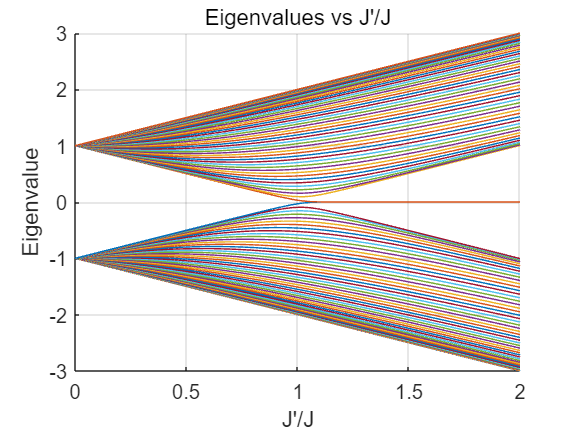

% Parameters
J = 1; % Reference hopping amplitude
N_sites = 50; % Number of a/b sites in the chain
J_prime_range = linspace(0, 2, 50); % J' range from 0 to 5J

% Initialize array to store eigenvalues
eigenvalues_all = zeros(length(J_prime_range), 2 * N_sites);

for k = 1:length(J_prime_range)
    J_prime = J_prime_range(k);
    
    % Define the Hamiltonian function for the SSH model
    H = H_SSH_chain_static(J, J_prime, N_sites);
    
    % Compute the eigenvalues of the Hamiltonian
    D = eig(H);
    
    % Store the eigenvalues
    eigenvalues_all(k, :) = sort(D);
end

% Plotting the eigenvalues
figure;
hold on;
for i = 1:2 * N_sites
    plot(J_prime_range, real(eigenvalues_all(:, i)), '-');
end
xlabel('J''/J');
ylabel('Eigenvalue');
title('Eigenvalues vs J''/J');
grid on;
hold off;


% Function to define the static SSH Hamiltonian

function H = H_SSH_chain_static(J, J_prime, N_sites)
    % Initialize the Hamiltonian matrix for the SSH chain
    H = zeros(2 * N_sites);
    
    for j = 1:N_sites
        % Index for a_j and b_j
        a_idx = 2 * j - 1;
        b_idx = 2 * j;
        
        % a_j to b_j hopping
        H(a_idx, b_idx) = J;
        H(b_idx, a_idx) = J;
        
        % b_j to a_{j+1} hopping
        if j < N_sites
            H(b_idx, a_idx + 2) = J_prime;
            H(a_idx + 2, b_idx) = J_prime;
        end
    end
end
